clear;clc;close all
layerfolder='../data/layers/';%route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 7.014698 seconds.


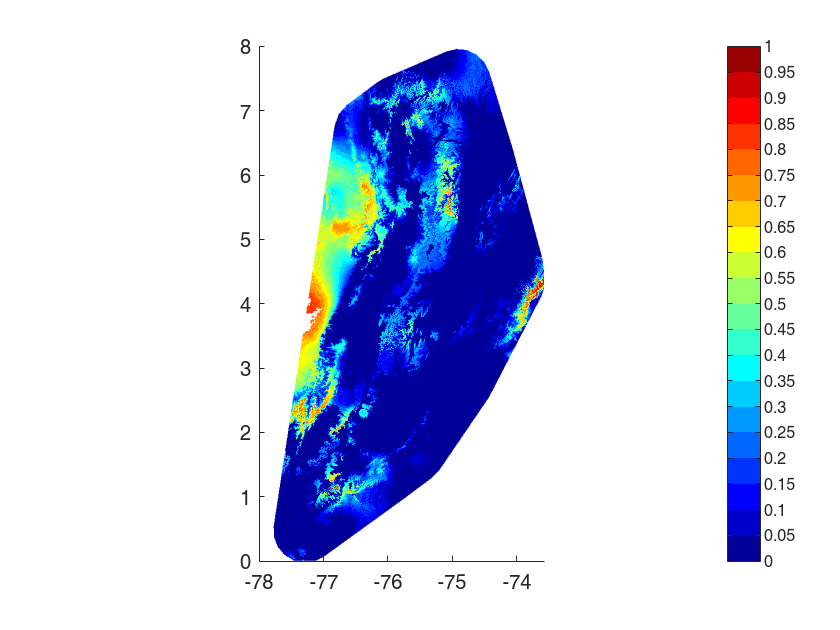

InfoInitialPoint = InitialPoint(Dimensions);
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

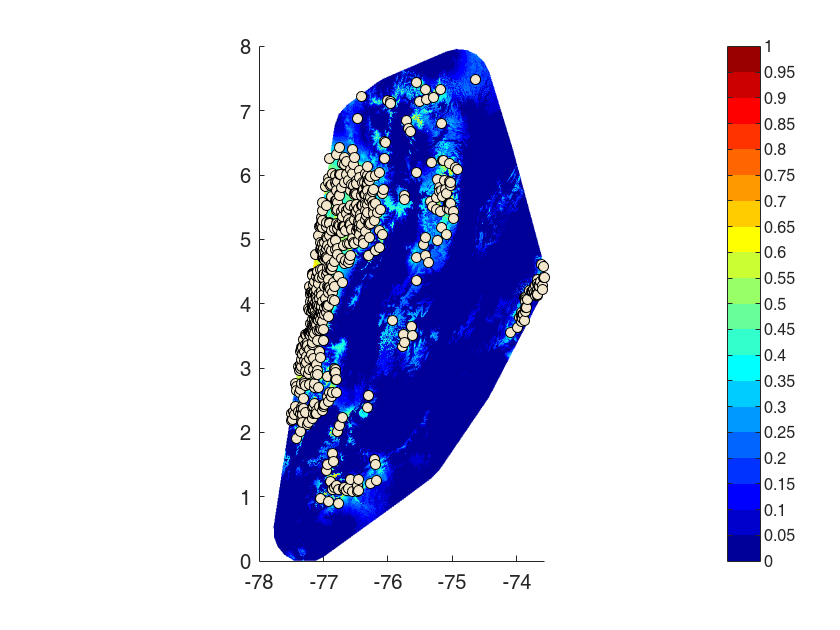

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 600, -3, true, 'GenSP', true, true);

----Finding clusters----


1 clusters identified


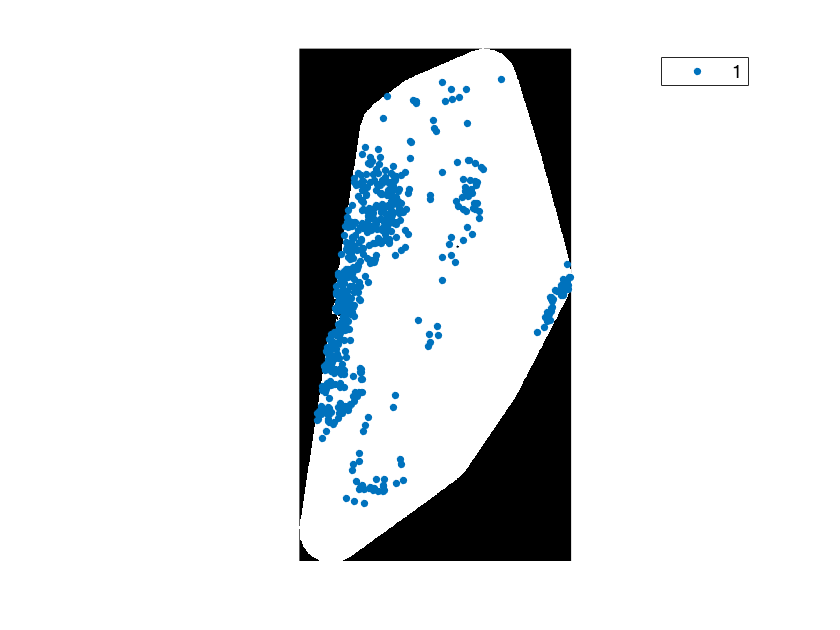

Elapsed time is 2.893832 seconds.
----Finding correlation----
Elapsed time is 7.971183 seconds.
----Creating predictors----
¡All done!
Elapsed time is 8.161648 seconds.


close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, true, false);

close all
show=false;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
pcaO(data{1},show,outlier,outlier2)

boundPointsIndex =      5
    14
    15
    20
    31
    35
    43
    49
    70
    89


boundPoints =     0.9422    0.9430    0.9462    0.7754    0.6477    0.5672    0.3095    0.6600    0.5508    0.6816    0.8967         0    0.6471    0.3939    0.8776    0.9911    0.0189    0.9327    0.9430
    0.9467    0.9474    0.9462    0.7719    0.6530    0.5310    0.3571    0.6720    0.5225    0.6680    0.9073    0.0000    0.6471    0.4808    0.8776    0.9911    0.0189    0.9327    0.9430
    0.9511    0.9474    0.9552    0.7539    0.7310    0.4293    0.5000    0.7115    0.4332    0.4256    0.9631    0.0233    0.7059    0.2992    0.8819    0.9956    0.0189    0.9372    0.9474
    0.9556    0.9561    0.9596    0.6711    0.7321    0.3690    0.5952    0.6749    0.3364    0.3476    0.9170    0.1628    0.7647    0.3376    0.9030    0.9911    0.1321    0.9417    0.9561
    0.9467    0.9430    0.9507    0.7681    0.6719    0.4845    0.4048    0.6888    0.4882    0.6529    0.9207    0.0000    0.6471    0.3862    0.8776    0.9911    0.0189    0.9372    0.9430
    0.9556    0.9561    0.9596 

radius =     0.3262    0.5958    0.7312    2.0523         0    0.2925    0.6255    1.1492    0.2937    0.6493    1.3324    2.1177    0.4190    0.1116    0.4030    0.6177    1.0480    2.1290    0.2596    0.5957    1.0555    0.3311    0.2015    0.2367    0.3309    0.6472    0.8701    2.0615    2.0718    0.1201    0.1511    0.4235    0.3659    0.4079    0.5356    0.5714    0.4320    0.2787    0.2492    0.7146    0.7208    1.3360    1.1716    0.4569    0.4003    0.3232    0.5788    0.6695    1.8856    0.5226
    0.2991    0.5714    0.7802    2.0278    0.1116    0.2497    0.6045    1.1894    0.3214    0.6340    1.3479    2.0963    0.4545         0    0.3818    0.5870    1.1020    2.1126    0.2284    0.5583    1.1064    0.3578    0.2177    0.2145    0.3144    0.6217    0.9155    2.0414    2.0477    0.1380    0.1252    0.4008    0.3996    0.4284    0.4965    0.5356    0.4389    0.2581    0.2178    0.6895    0.7243    1.3461    1.2294    0.5288    0.4058    0.3358    0.5480    0.6491    1.8802

classifiers =     0.2023    0.0944    0.3246    0.4975         0    0.1755    0.1688    0.5039    0.2807    0.3032    0.4417    0.3352    0.1321         0         0    0.1490    0.3573    0.6546    0.1827         0    0.4808    0.2570    0.1743    0.1658    0.0833    0.1644    0.5198    0.5418    0.5351    0.1201         0    0.2258    0.1895    0.1843         0    0.1370    0.2290    0.1542    0.1446    0.2966    0.4900    0.4808         0    0.1946    0.2452    0.3232    0.1449    0.1902         0    0.2649


newpoints =     0.3413    0.5295    0.4434    0.5048    0.5254    0.4816    0.6786    0.5337    0.8034    0.4683    0.4392    0.7052    0.6117    0.5597    0.5735    0.5240    0.7163    0.5744    0.4538    0.5635    0.6454    0.6199    0.8375    0.6831    0.6717    0.3752    0.4082    0.5546    0.6653    0.5745    0.5430    0.4694    0.6261    0.5847    0.6194    0.3976    0.5803    0.5480    0.4472    0.7593    0.5360    0.7611    0.5170    0.6098    0.4794    0.5058    0.6484    0.6465    0.6606    0.5898


ans =     0.5196    0.2186    0.3794    0.2763    0.2351    0.3237    0.0412    0.2021    0.0082    0.3505    0.3835    0.0309    0.0928    0.1608    0.1423    0.2392    0.0268    0.1402    0.3608    0.1546    0.0680    0.0825    0.0021    0.0412    0.0474    0.4722    0.4330    0.1753    0.0536    0.1402    0.1856    0.3505    0.0804    0.1216    0.0825    0.4412    0.1237    0.1794    0.3711    0.0103    0.1959    0.0103    0.2557    0.0948    0.3320    0.2763    0.0660    0.0660    0.0598    0.1196


----Modeling----


ij = 1

-Model 1


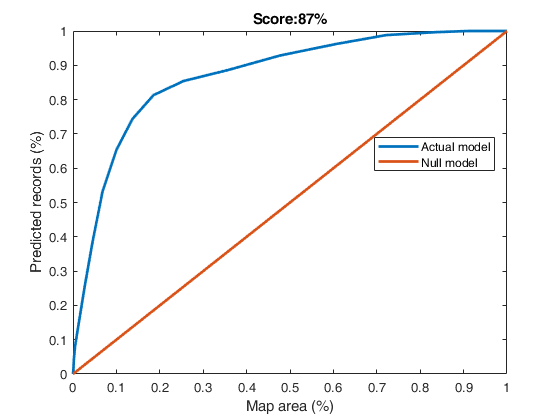

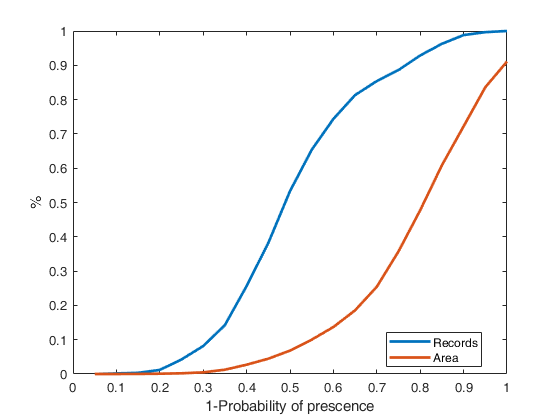

Elapsed time is 2.619780 seconds.


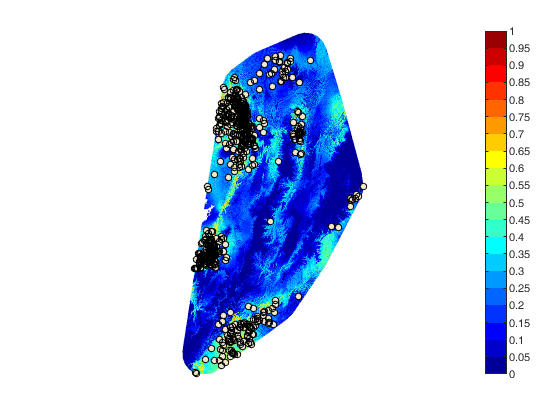

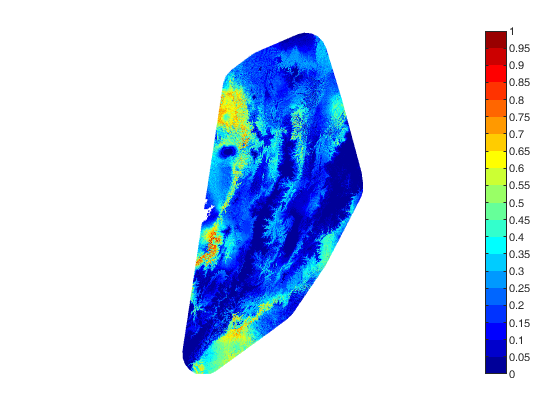

dataf = bnm_modeling(data, '', true, 4, false);

close all
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
data = bnm_modeling2(data{1},show,outlier,outlier2)